cAMPFreSimulation_paraScan

分析不同参数对一个周期内蛋白平均表达$\bar y$的影响

Shuai Yang 2023/2/21

clear

P = 0.1; % 占空比(0,1]
gamma = 0.002876;% s-1,cAMP降解率 gamma;
beta = 0.2; % s-1, bPAC失活率
alpha =0.00225;% alpha = k/K1;调节Vfr-cAMP2浓度
lambda = 27;% lambda = Vfr/K2;调节激活DNA。

#### % 数值积分模拟蛋白输出Tset = 50:50:2400;

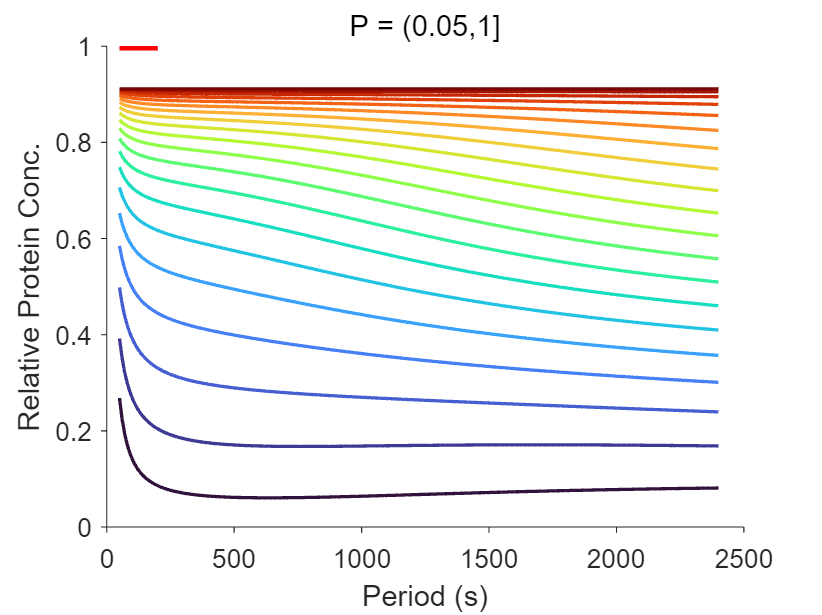

scanPara = P;
Pset = 0.05:0.05:1;
mymap = turbo(numel(Pset));
f1 = figure;
ax1 = axes('Parent',f1);
for iScan = 1:numel(Pset)
    P = Pset(iScan);
    Tset = 50:10:2400;
    y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda);
    plot(Tset,y,'Color',mymap(iScan,:),'LineWidth',1.5);
    hold on
end

line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
colormap(ax1,mymap)
title(ax1,'P = (0.05,1]','Interpreter','none')

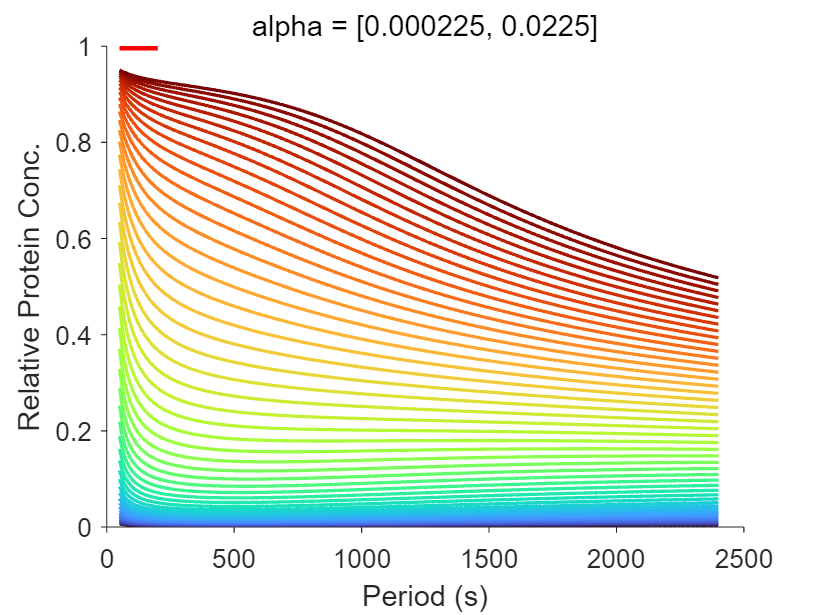

P = scanPara;% 还原默认值

scanPara = alpha;
scanSet = logspace(log10(scanPara/10),log10(scanPara*10),50);
mymap = turbo(numel(scanSet));
f1 = figure;
ax1 = axes('Parent',f1);
for iScan = 1:numel(scanSet)
    alpha= scanSet(iScan);
    Tset = 50:10:2400;
    y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda);
    plot(Tset,y,'Color',mymap(iScan,:),'LineWidth',1.5);
    hold on
end

line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
colormap(ax1,mymap)
title(ax1,['alpha = [',num2str(scanSet(1)),', ',num2str(scanSet(end)),']'], ...
    'Interpreter','none')

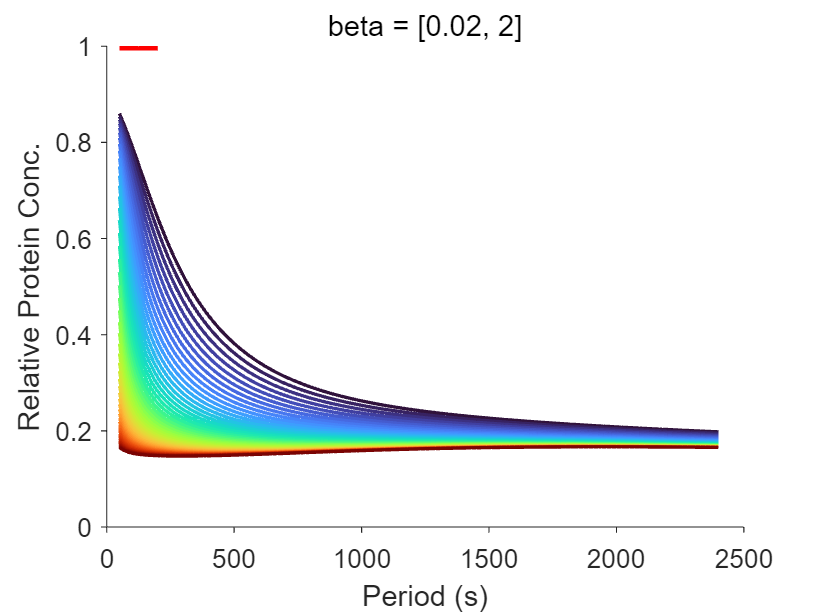

alpha = scanPara;

scanPara = beta;
scanSet = logspace(log10(scanPara/10),log10(scanPara*10),50);
mymap = turbo(numel(scanSet));
f1 = figure;
ax1 = axes('Parent',f1);
for iScan = 1:numel(scanSet)
    beta= scanSet(iScan);
    Tset = 50:10:2400;
    y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda);
    plot(Tset,y,'Color',mymap(iScan,:),'LineWidth',1.5);
    hold on
end

line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
colormap(ax1,mymap)
title(ax1,['beta = [',num2str(scanSet(1)),', ',num2str(scanSet(end)),']'], ...
    'Interpreter','none')

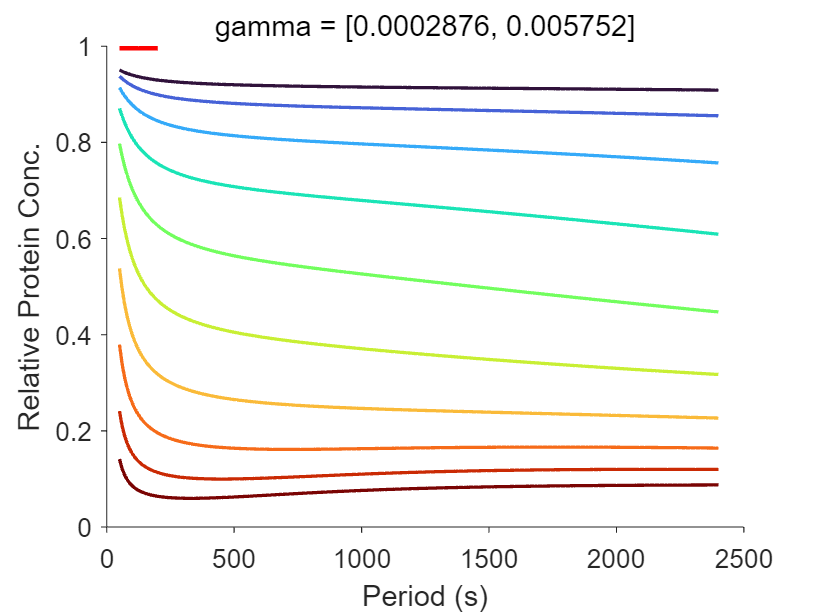

beta = scanPara;



scanPara = gamma;
scanSet = logspace(log10(scanPara/10),log10(scanPara*2),10);
mymap = turbo(numel(scanSet));
f1 = figure;
ax1 = axes('Parent',f1);
for iScan = 1:numel(scanSet)
    gamma= scanSet(iScan);
    Tset = 50:10:2400;
    y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda);
    plot(Tset,y,'Color',mymap(iScan,:),'LineWidth',1.5);
    hold on
end

line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
colormap(ax1,mymap)
title(ax1,['gamma = [',num2str(scanSet(1)),', ',num2str(scanSet(end)),']'], ...
    'Interpreter','none')

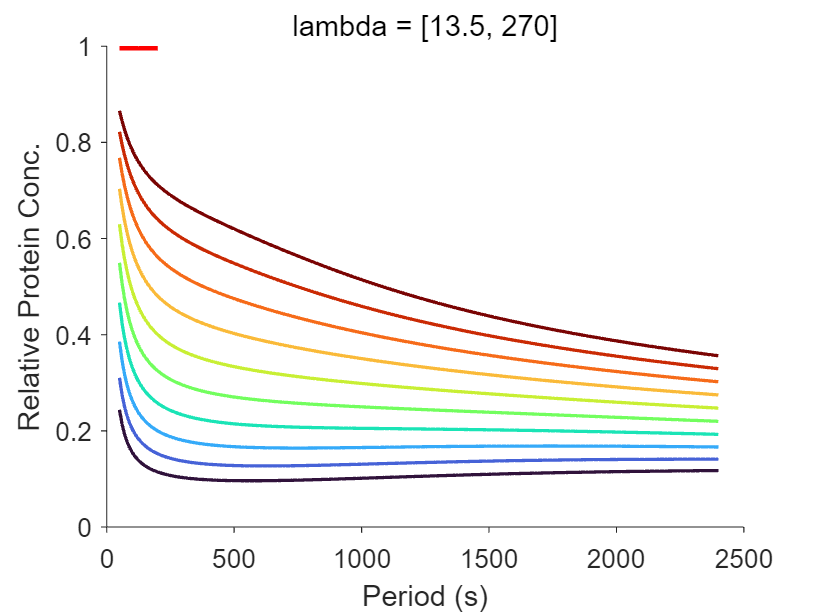

gamma = scanPara;

scanPara = lambda;
scanSet = logspace(log10(scanPara/2),log10(scanPara*10),10);
mymap = turbo(numel(scanSet));
f1 = figure;
ax1 = axes('Parent',f1);
for iScan = 1:numel(scanSet)
    lambda= scanSet(iScan);
    Tset = 50:10:2400;
    y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda);
    plot(Tset,y,'Color',mymap(iScan,:),'LineWidth',1.5);
    hold on
end

line([50,200],[1,1],'LineWidth',4,'Color','r')
ylim(ax1,[0,1]);
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'Period (s)')
ylabel(ax1,'Relative Protein Conc.')
colormap(ax1,mymap)
title(ax1,['lambda = [',num2str(scanSet(1)),', ',num2str(scanSet(end)),']'], ...
    'Interpreter','none')

lambda = scanPara;


function y = proteinIntegral(Tset,gamma,beta,P,alpha,lambda)

y = NaN(size(Tset));
for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid);
    fun = @(t,T) actDNAOutPut1(t,T,gamma,beta,P,alpha,lambda);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;
    y(iPeroid) = q1;
end
end

function x1 = cAMPOutPut1(t,T,gamma,beta,P)

x_Mid1 = (1/(beta-gamma)*(exp(-gamma*T)-exp(-beta*T+beta*T*P-gamma*T*P)) ...
    +1/gamma*(1-exp(-gamma*T*P)))/(1-exp(-gamma*T));
x_Low1 = x_Mid1*exp(-gamma*(T-T*P))...
    +1/(beta-gamma)*(exp(-gamma*(T-T*P))-exp(-beta*(T-T*P)));

x1 = ((x_Low1-1/gamma)*exp(-gamma*t)+1/gamma).*(t<=T*P)+...
    ((x_Mid1+1/(beta-gamma))*exp(-gamma*(t-T*P)) ...
    -1/(beta-gamma)*exp(-beta*(t-T*P))).*(t>T*P);

end

function u1 = actDNAOutPut1(t,T,gamma,beta,P,alpha,lambda)
% t 时间 T 周期

x1 = cAMPOutPut1(t,T,gamma,beta,P);
u1 = lambda./((1+lambda)+1./(x1*alpha).^2);

end